close all
clear variables

% Load the flower images into a dataset

flowersDataset = fullfile("17flowers/");

% Images are stored in a folder with their label type
imds = imageDatastore(flowersDataset, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

numTrainFiles = 80 * 0.8;
[trainingSet,validationSet] = splitEachLabel(imds,numTrainFiles,'randomized');

countEachLabel(trainingSet)

ans = 17×2 table
       Label       Count
    ___________    _____

    Bluebell        64  
    Buttercup       64  
    Colts' Foot     64  
    Cowslip         64  
    Crocus          64  
    Daffodil        64  
    Daisy           64  
    Dandelion       64  
    Fritillary      64  
    Iris            64  
    LilyValley      64  
    Pansy           64  
    Snowdrop        64  
    Sunflower       64  
    Tigerlily       64  
    Tulip           64  


countEachLabel(validationSet)

ans = 17×2 table
       Label       Count
    ___________    _____

    Bluebell        16  
    Buttercup       16  
    Colts' Foot     16  
    Cowslip         16  
    Crocus          16  
    Daffodil        16  
    Daisy           16  
    Dandelion       16  
    Fritillary      16  
    Iris            16  
    LilyValley      16  
    Pansy           16  
    Snowdrop        16  
    Sunflower       16  
    Tigerlily       16  
    Tulip           16  


trainingSet.ReadSize = 6;
validationSet.ReadSize = 6;

trainingSet = transform(trainingSet, @imageAug, 'IncludeInfo',true);
validationSet = transform(validationSet, @imageAug, 'IncludeInfo',true);

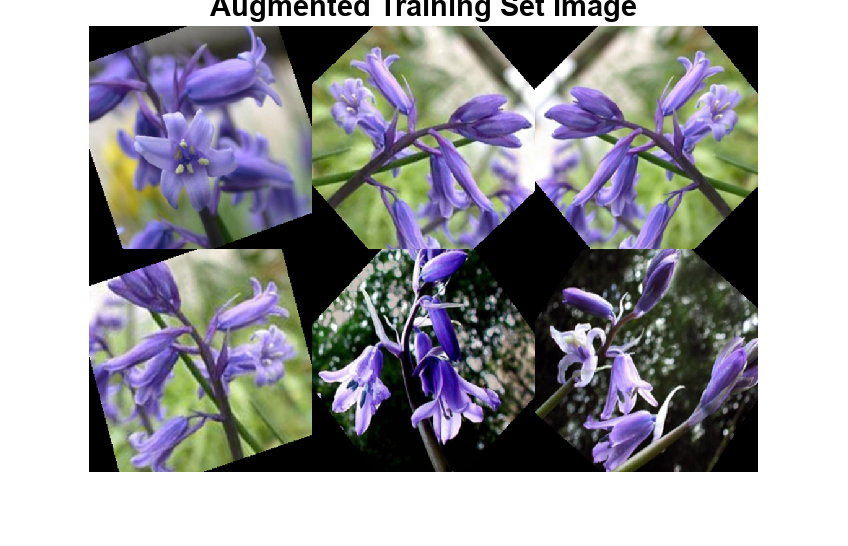

figure;
ims = preview(trainingSet);
ims = ims(:,1);
montage(ims(:));
title("Augmented Training Set Image");

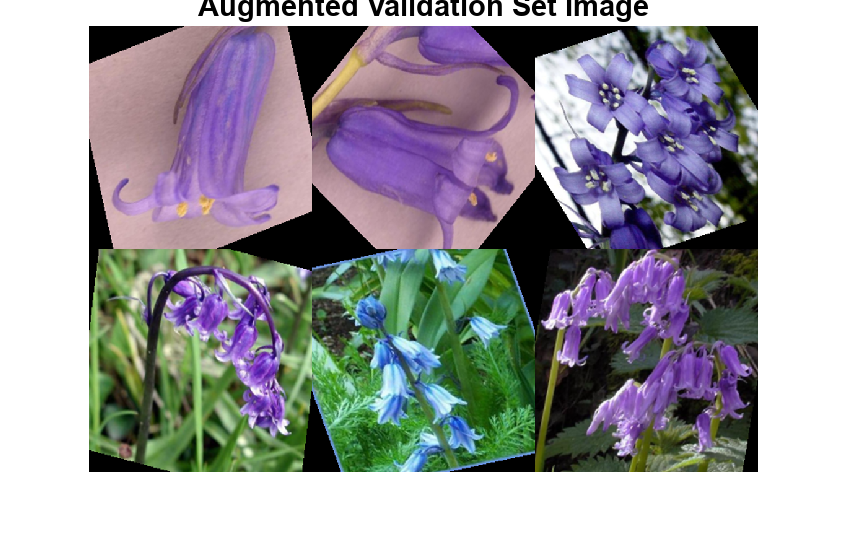


figure;
ims = preview(validationSet);
ims = ims(:,1);
montage(ims(:));
title("Augmented Validation Set Image");


% trainingSet.UnderlyingDatastores{1}.ReadSize = 1;
% validationSet.UnderlyingDatastores{1}.ReadSize = 1;


inputSize = [256 256 3];
numClasses = 17;

layers = [
    imageInputLayer(inputSize)

    convolution2dLayer(4,64)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'stride', 2)

    convolution2dLayer(4,128)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'stride', 2)

    convolution2dLayer(4,256)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'stride', 2)

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ]

layers =   16×1 Layer array with layers:

     1   ''   Image Input             256×256×3 images with 'zerocenter' normalization
     2   ''   2-D Convolution         64 4×4 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   2-D Convolution         128 4×4 convolutions with stride [1  1] and padding [0  0  0  0]
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   ''   2-D Convolution         256 4×4 convolutions with stride [1  1] and padding [0  0  0  0]
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU            


options = trainingOptions('sgdm', ...
    'MiniBatchSize',64,...
    'MaxEpochs',30, ...
    'InitialLearnRate',0.001,...
    'ValidationData',validationSet, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','multi-gpu')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 64
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.TransformedDatastore]
             ValidationFrequency: 30
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'multi-gpu'
                      WorkerL

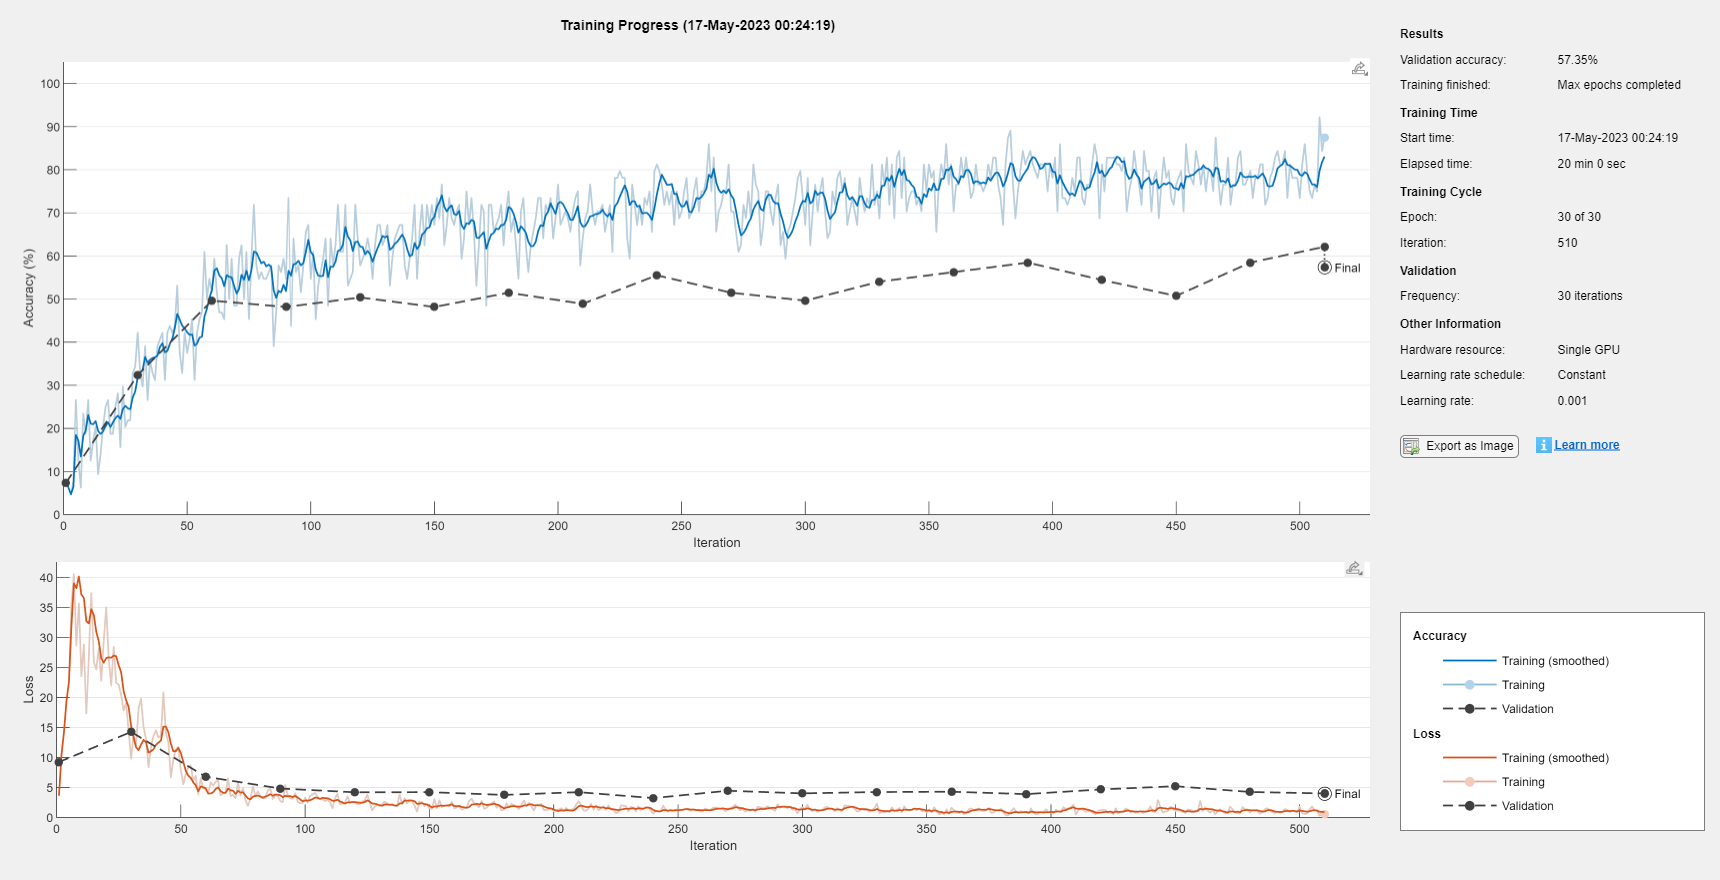

%classifier = trainNetwork(trainingSet, layers,options);

%save('classnet.mat', 'classifier')

load('classnet.mat', 'classifier')

 deepNetworkDesigner(classifier);

predictedLabels = predict(classifier, validationSet, 'ReturnCategorical', true);
predictedTrainingLabels = predict(classifier, trainingSet, 'ReturnCategorical', true);

figure;
confMat = confusionmat(validationSet.UnderlyingDatastores{1}.Labels, predictedLabels);
helperDisplayConfusionMatrix(confMat)

digit  | 0        1        2        3        4        5        6        7        8        9        10       11       12       13       14       15       16       
------------------------------------------------------------------------------------------------------------------------------------------------------------------
     1 | 0.44     0.00     0.00     0.00     0.44     0.00     0.00     0.00     0.00     0.00     0.00     0.12     0.00     0.00     0.00     0.00     0.00     
     2 | 0.00     0.50     0.12     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.12     0.00     0.00     0.00     0.25     0.00     
     3 | 0.00     0.00     0.75     0.00     0.00     0.00     0.00     0.06     0.00     0.00     0.00     0.00     0.06     0.00     0.00     0.12     0.00     
     4 | 0.00     0.12     0.12     0.19     0.06     0.06     0.00     0.06     0.00     0.00     0.00     0.00     0.06     0.06     0.00     0.25     0.00     
     5 | 0.06     0.00

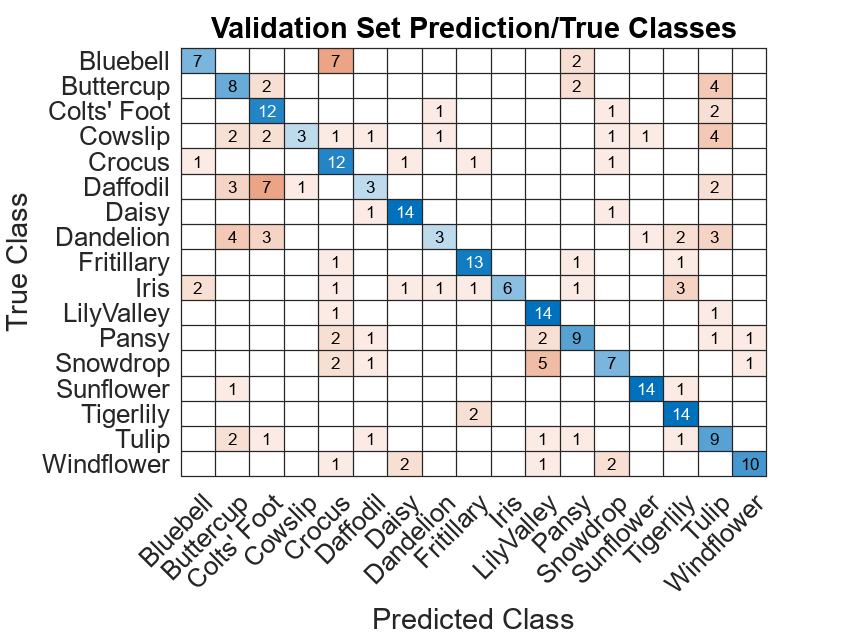

confusionchart(confMat, unique(validationSet.UnderlyingDatastores{1}.Labels))
title("Validation Set Prediction/True Classes");


accuracy = mean(predictedLabels == validationSet.UnderlyingDatastores{1}.Labels)

accuracy = 0.5809

precision = mean(diag(confMat) ./ sum(confMat,2));
recall = mean(diag(confMat) ./ sum(confMat,1)');
F1score = 2 * (precision * recall) / (precision + recall);

precision

precision = 0.5809

recall

recall = 0.6201

F1score

F1score = 0.5998

figure;
confMat = confusionmat(trainingSet.UnderlyingDatastores{1}.Labels, predictedTrainingLabels);
helperDisplayConfusionMatrix(confMat)

digit  | 0        1        2        3        4        5        6        7        8        9        10       11       12       13       14       15       16       
------------------------------------------------------------------------------------------------------------------------------------------------------------------
     1 | 0.86     0.00     0.00     0.00     0.08     0.00     0.00     0.00     0.00     0.00     0.05     0.00     0.02     0.00     0.00     0.00     0.00     
     2 | 0.00     0.89     0.02     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.09     0.00     
     3 | 0.00     0.00     0.97     0.00     0.00     0.02     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.00     0.02     0.00     
     4 | 0.00     0.17     0.06     0.20     0.02     0.05     0.00     0.02     0.00     0.00     0.06     0.00     0.05     0.02     0.09     0.25     0.02     
     5 | 0.00     0.00

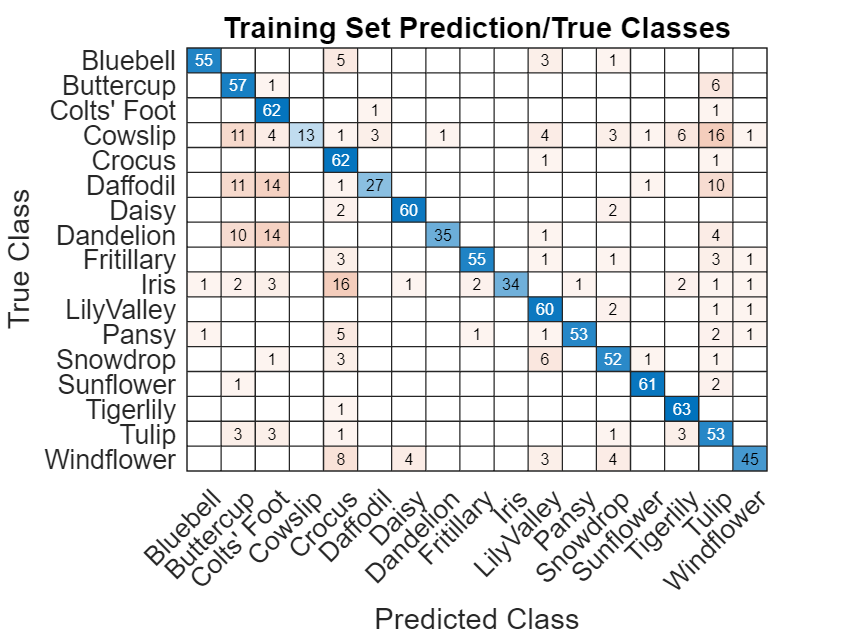

confusionchart(confMat, unique(trainingSet.UnderlyingDatastores{1}.Labels))
title("Training Set Prediction/True Classes");


accuracy = mean(predictedTrainingLabels == trainingSet.UnderlyingDatastores{1}.Labels)

accuracy = 0.7785

precision = mean(diag(confMat) ./ sum(confMat,2));
recall = mean(diag(confMat) ./ sum(confMat,1)');
F1score = 2 * (precision * recall) / (precision + recall);

precision

precision = 0.7785

recall

recall = 0.8359

F1score

F1score = 0.8062

function helperDisplayConfusionMatrix(confMat)
% Display the confusion matrix in a formatted table.

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2));

digits = 1:17;
colHeadings = arrayfun(@(x)sprintf('%d',x),0:16,'UniformOutput',false);
format = repmat('%-9s',1,11);
header = sprintf(format,'digit  |',colHeadings{:});
fprintf('\n%s\n%s\n',header,repmat('-',size(header)));
for idx = 1:numel(digits)
    fprintf('%6d%-s',digits(idx),  ' | ');
    fprintf('%-9.2f', confMat(idx,:));
    fprintf('\n')
end
end

function [dataOut,info] = imageAug(dataIn,info)
% Custom augmentation function from the tutorial
dataOut = cell([size(dataIn,1),2]);


for i = 1:size(dataIn,1)
    temp = dataIn{i};
    
    temp = imresize(temp, [256, 256]);

    tform = randomAffine2d(Scale=[0.95,1.05],Rotation=[-45 45],XShear=[-10 10],YShear=[-10 10]);
    outputView = affineOutputView(size(temp),tform);
    temp = imwarp(temp,tform,OutputView=outputView);


    % Form second column expected by trainNetwork which is the expected response,
    % the categorical label in this case
    dataOut(i,:) = {temp,info.Label(i)};
end

end
